% NO SETUP - ONLY ABSORBERS
recordtime = 1  % [s]

recordtime = 1

nosetup_filename = "2020_11_26\1_no_setup.mat"; % Data with plain concrete
nosetup = load_ancortek_data(nosetup_filename);
disp(nosetup.props);

        DateTime: '26-Nov-2020 10:34:53'
       SweepTime: 1.0000e-03
      RecordTime: 9.9990
             NTS: 128
         NSweeps: 9999
         NPulses: 9999
        waveform: 'FMCW_SAWTOOTH'
              f0: 2.5000e+10
              BW: 2.0000e+09
          fslope: 2.0000e+12
         NRanges: 128
    SamplingRate: 128000
    SamplingFreq: 1000
        RangeRes: 0.0749
        RangeMax: 9.5934
              dR: 0.0749
              dt: 2.5000e-10
             NCh: 2




NRanges = nosetup.props.NRanges;
NPulses = nosetup.props.NPulses;
t = (1:NRanges) * nosetup.props.SweepTime / NRanges;

nPulses = recordtime / nosetup.props.SweepTime

nPulses = 1000

nosetup_x = mean(nosetup.datamatrix(:, 1:nPulses, :), [1, 2]);  % averaged over 2 channels and nPulses
nosetup_x = squeeze(nosetup_x - mean(nosetup_x));

figure
subplot(2, 1, 1)
plot(t, abs(nosetup_x));

nosetup_spectrum = power_spectrum(nosetup_x, '2-sided');
R = (1:NRanges)*nosetup.props.dR;

subplot(2, 1, 2)
plot(R, nosetup_spectrum.P);

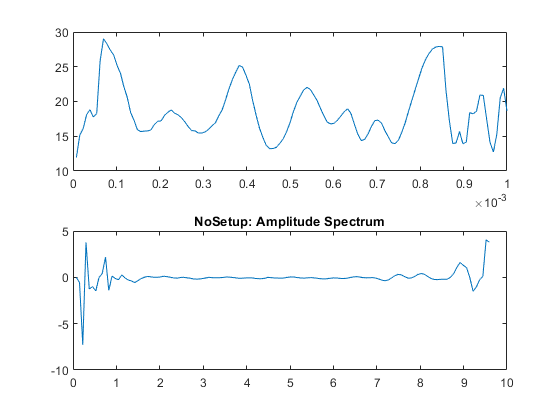

title("NoSetup: Amplitude Spectrum");

% ONLY FRAME
recordtime = 1  % [s]

recordtime = 1

frame_filename = "2020_11_26\2-only_frame-no_absorbers.mat"; % Data with plain concrete
frame = load_ancortek_data(frame_filename);
disp(frame.props);

        DateTime: '26-Nov-2020 10:38:53'
       SweepTime: 1.0000e-03
      RecordTime: 9.9990
             NTS: 128
         NSweeps: 9999
         NPulses: 9999
        waveform: 'FMCW_SAWTOOTH'
              f0: 2.5000e+10
              BW: 2.0000e+09
          fslope: 2.0000e+12
         NRanges: 128
    SamplingRate: 128000
    SamplingFreq: 1000
        RangeRes: 0.0749
        RangeMax: 9.5934
              dR: 0.0749
              dt: 2.5000e-10
             NCh: 2




NRanges = frame.props.NRanges;
NPulses = frame.props.NPulses;
t = (1:NRanges) * frame.props.SweepTime / NRanges;

nPulses = recordtime / frame.props.SweepTime

nPulses = 1000

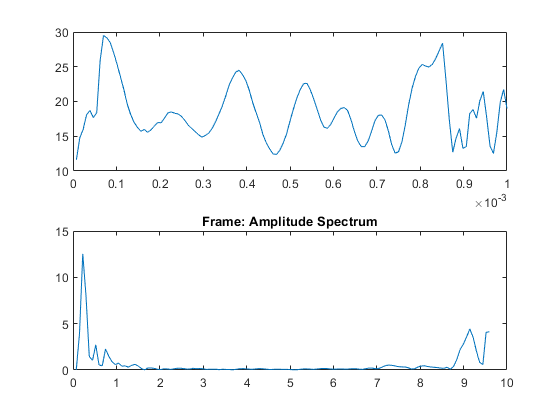

frame_x = mean(frame.datamatrix(:, 1:nPulses, :), [1, 2]);  % averaged over 2 channels and nPulses
frame_x = squeeze(frame_x - mean(frame_x));

figure
subplot(2, 1, 1)
plot(t, abs(frame_x));

frame_spectrum = power_spectrum(frame_x, '2-sided');
R = (1:NRanges)*frame.props.dR;

subplot(2, 1, 2)
plot(R, abs(frame_spectrum.P));
title("Frame: Amplitude Spectrum");

% PLAIN CEMENT CONCRETE
recordtime = 1  % [s]

recordtime = 1

PCC_filename = "2020_11_26\3-plain_concrete.mat"; % Data with plain concrete
pcc = load_ancortek_data(PCC_filename);
disp(pcc.props);

        DateTime: '26-Nov-2020 12:07:22'
       SweepTime: 1.0000e-03
      RecordTime: 9.9990
             NTS: 128
         NSweeps: 9999
         NPulses: 9999
        waveform: 'FMCW_SAWTOOTH'
              f0: 2.5000e+10
              BW: 2.0000e+09
          fslope: 2.0000e+12
         NRanges: 128
    SamplingRate: 128000
    SamplingFreq: 1000
        RangeRes: 0.0749
        RangeMax: 9.5934
              dR: 0.0749
              dt: 2.5000e-10
             NCh: 2




NRanges = pcc.props.NRanges;
NPulses = pcc.props.NPulses;
t = (1:NRanges) * pcc.props.SweepTime / NRanges;

nPulses = recordtime / pcc.props.SweepTime

nPulses = 1000

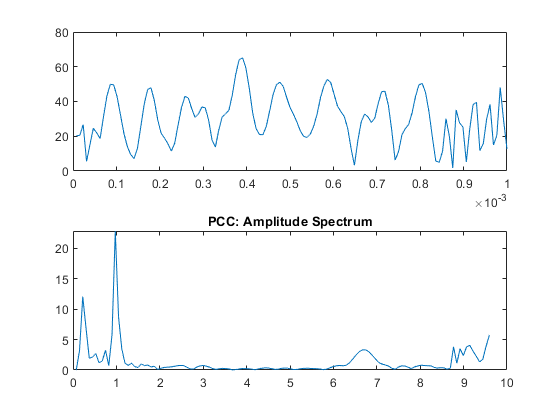

pcc_x = mean(pcc.datamatrix(:, 1:nPulses, :), [1, 2]);  % averaged over 2 channels and nPulses
pcc_x = squeeze(pcc_x - mean(pcc_x));

figure
subplot(2, 1, 1)
plot(t, abs(pcc_x));

pcc_spectrum = power_spectrum(pcc_x, '2-sided');
R = (1:NRanges)*pcc.props.dR;

subplot(2, 1, 2)
plot(R, abs(pcc_spectrum.P));
title("PCC: Amplitude Spectrum");

% FIBRE CONCRETE
recordtime = 1  % [s]

recordtime = 1

uhpc_filename = "2020_11_26\4-UHPC_Vf05.mat"; % Data with plain concrete
uhpc = load_ancortek_data(uhpc_filename);
disp(uhpc.props);

        DateTime: '26-Nov-2020 12:21:15'
       SweepTime: 1.0000e-03
      RecordTime: 9.9990
             NTS: 128
         NSweeps: 9999
         NPulses: 9999
        waveform: 'FMCW_SAWTOOTH'
              f0: 2.5000e+10
              BW: 2.0000e+09
          fslope: 2.0000e+12
         NRanges: 128
    SamplingRate: 128000
    SamplingFreq: 1000
        RangeRes: 0.0749
        RangeMax: 9.5934
              dR: 0.0749
              dt: 2.5000e-10
             NCh: 2




NRanges = uhpc.props.NRanges;
NPulses = uhpc.props.NPulses;
t = (1:NRanges) * uhpc.props.SweepTime / NRanges;

nPulses = recordtime / uhpc.props.SweepTime

nPulses = 1000

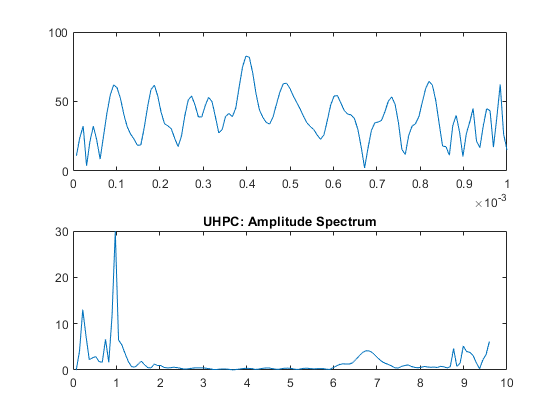

uhpc_x = mean(uhpc.datamatrix(:, 1:nPulses, :), [1, 2]);  % averaged over 2 channels and nPulses
uhpc_x = squeeze(uhpc_x - mean(uhpc_x));

figure
subplot(2, 1, 1)
plot(t, abs(uhpc_x));

uhpc_spectrum = power_spectrum(uhpc_x, '2-sided');
R = (1:NRanges)*uhpc.props.dR;

subplot(2, 1, 2)
plot(R, abs(uhpc_spectrum.P));
title("UHPC: Amplitude Spectrum");

[If, indxf] = max(uhpc_spectrum.P)

If = -10.7756 - 28.0455i

indxf = 13

[Ic, indxc] = max(pcc_spectrum.P)

Ic = 12.6192 - 19.0682i

indxc = 13

r = abs(If) / abs(Ic)  % ratio of intensities

r = 1.3140

[indxc, indxf]

ans =     13    13


thetaf = angle(uhpc_spectrum.P(indxf)) % phase - fibre concrete

thetaf = -1.9376

thetac = angle(pcc_spectrum.P(indxc))  % phase - plain concrete

thetac = -0.9862

% Fibre content
lf = 13;  % fibre length
df = 0.2;
As = lf / df

As = 65

e = sqrt(1 - 1/As^2)

e = 0.9999

N1 = (log((1+e)/(1-e)) - 2*e) * (1-e^2) / (2*e^3);
N1 = 0;
N2 = 0.5*(1-N1)

N2 = 0.5000

N3 = N2

N3 = 0.5000

If_amp = abs(If);
Ic_amp = abs(Ic);
rel_eps_uhpc = ((1+If_amp)/(1-If_amp)) * ((1-Ic_amp)/(1+Ic_amp))

rel_eps_uhpc = 0.9793

sumN = (1/N1 + 1/N2 + 1/N3)

sumN = Inf

k = rel_eps_uhpc - 1

k = -0.0207

vol_frac = 1 / (1 + 3*k/ sumN)

vol_frac = 1